clear all
close all
clc

## 11.7.1

syms t w
A = 5;
T = 3;
xt = piecewise(t<=0,0, 0<=t<=T,A/T*t, t>=T,0);
FTrans = int(xt*exp(-1j*w*t),t,-inf,inf)

$$FTrans = -\frac{5}{3\,w^{2}}+\frac{5\,{\mathrm{e}}^{-3\,w\,\mathrm{i}}\,\left(1+3\,w\,\mathrm{i}\right)}{3\,w^{2}}$$

## 11.7.3

syms t w
A = 12;
T = 3;
xt = piecewise(0>t,0, 0<t<T/3,A, T/3<t<2*T/3,2/3*A, 2/3*T<t<T,A/3, T<t,0);
FTrans = int(xt*exp(1j*w*t),t,-inf,inf)

$$FTrans = \frac{16\,\sin\left(\frac{w}{2}\right)\,{\mathrm{e}}^{\frac{3\,w\,\mathrm{i}}{2}}}{w}+\frac{8\,\sin\left(\frac{w}{2}\right)\,{\mathrm{e}}^{\frac{5\,w\,\mathrm{i}}{2}}}{w}+\frac{24\,\sin\left(\frac{w}{2}\right)\,\left(\cos\left(\frac{w}{2}\right)+\sin\left(\frac{w}{2}\right)\,\mathrm{i}\right)}{w}$$

## 11.7.4

syms t w
A = 2;
T = 12;
xt = piecewise(0>t,0, 0<t<T/3,A, T/3<t<2*T/3,-1/4*t+3, 2*T/3<t<T,A/2, T<t,0);
FTrans = int(xt*exp(1j*w*t),t,-inf,inf)

$$FTrans = -\frac{{\mathrm{e}}^{4\,w\,\mathrm{i}}\,\left({\mathrm{e}}^{4\,w\,\mathrm{i}}-1\right)}{4\,w^{2}}+\frac{{\mathrm{e}}^{4\,w\,\mathrm{i}}\,\left(8\,{\mathrm{e}}^{4\,w\,\mathrm{i}}\,\mathrm{i}+24\,\sin\left(2\,w\right)\,{\mathrm{e}}^{2\,w\,\mathrm{i}}-4\,\mathrm{i}\right)}{4\,w}+\frac{2\,\sin\left(2\,w\right)\,{\mathrm{e}}^{10\,w\,\mathrm{i}}}{w}+\frac{4\,\sin\left(2\,w\right)\,\left(\cos\left(2\,w\right)+\sin\left(2\,w\right)\,\mathrm{i}\right)}{w}$$

## 11.7.8

A = 5;
T = 1;
alpha = 10;
xt = piecewise(0<t<T,A*(1-exp(-alpha*t)), T<t, 0);
FTrans = int(xt*exp(1j*w*t),t,-inf,inf)

$$FTrans = \mathrm{NaN}$$

## 11.8.3

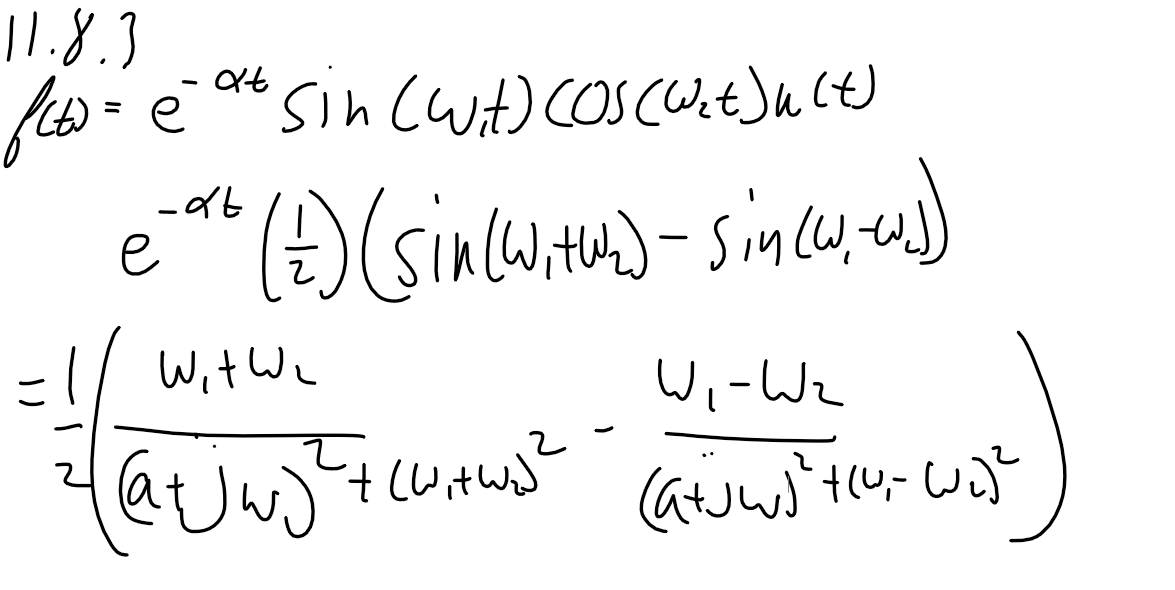

syms t w
alpha = .5;
w_one = 4;
w_two = 2;
Fw = (1/2)*((w_one+w_two)/((alpha+1j*w)^2+(w_one+w_two)^2)-(w_one-w_two)/((alpha+1j*w)^2+(w_one-w_two)^2))

$$Fw = -\frac{1}{{\left(\frac{1}{2}+w\,\mathrm{i}\right)}^{2}+4}+\frac{3}{{\left(\frac{1}{2}+w\,\mathrm{i}\right)}^{2}+36}$$


gt = t*exp(-alpha * t)*exp(-1j*w*t);
Gw = int(gt,t,0,10*alpha)

$$Gw = \frac{1}{{\left(\frac{1}{2}+w\,\mathrm{i}\right)}^{2}}-\frac{{\mathrm{e}}^{-\frac{5}{2}-5\,w\,\mathrm{i}}\,\left(\frac{7}{2}+5\,w\,\mathrm{i}\right)}{{\left(\frac{1}{2}+w\,\mathrm{i}\right)}^{2}}$$

## 11.8.6